% collect elements in a dose table into matrix form
% assume table has the following variables
%  - conc1
%  - conc2
%  - effect

% goal is to put it into a matrix, with conc1 and conc2 as the axes
clear;clc;close all
data = readtable('data-hts-invert.csv');

conc1 = data.c1;
conc2 = data.c2;
conc3 = data.c3;

cellLine = 6

cellLine = 6

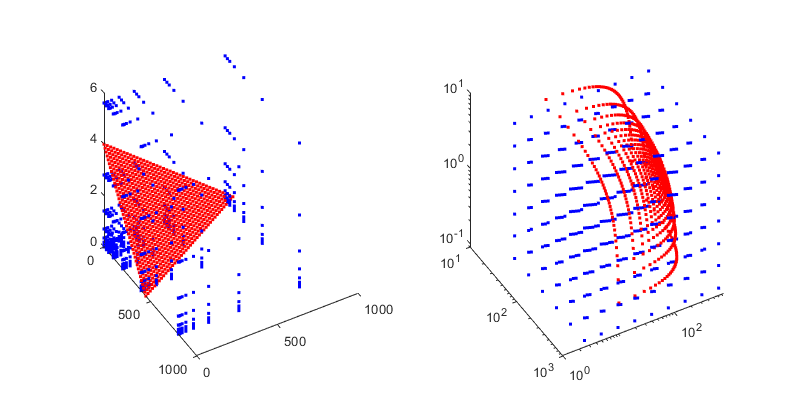


effect = 1 - data{:,cellLine + 4}; % back to growth inhibition

% find unique doses
[doses1, indConc1, indDose1] = unique(conc1);
% doses = conc1(indConc), conc = doses(indDose);
[doses2, indConc2, indDose2] = unique(conc2);
[doses3, indConc3, indDose3] = unique(conc3);
[X, Y, Z] = meshgrid(doses1, doses2, doses3); % can also use ndgrid, different orientation
result = accumarray( [indDose2(:), indDose1(:), indDose3(:)], effect, [], [], NaN ); % insert NaN if no value found

doseMatrix = result;


xmax = 450;
ymax = 800;
zmax = 4;

% Attempt a interp3 on a new grid
x = linspace(0, xmax, 40);
y = linspace(0, ymax, 40);
z = linspace(0, zmax, 40);
[X2,Y2,Z2] = meshgrid(x,y,z);

tiledlayout(1, 2)
nexttile

plot3(X(:), Y(:), Z(:), '.b')
hold on
%plot3(X2(:), Y2(:), Z2(:), '.r')
hold off

effect2 = interp3(X, Y, Z, doseMatrix, X2, Y2, Z2);

Xnorm = X2./max(x);
Ynorm = Y2./max(y);
Znorm = Z2./max(z);

sumAll = Xnorm + Ynorm + Znorm;
ind = find(sumAll > 1+0.01 | sumAll < 1-0.01);
X3 = X2;
Y3 = Y2;
Z3 = Z2;

Xnorm(ind) = [];
Ynorm(ind) = [];
Znorm(ind) = [];
effect2(ind) = [];

X3(ind) = [];
Y3(ind) = [];
Z3(ind) = [];

hold on
plot3(X3(:), Y3(:), Z3(:), '.r')
hold off
view([60.01 39.22])
nexttile
plot3(X(:), Y(:), Z(:), '.b')
hold on
hold off
hold on
plot3(X3(:), Y3(:), Z3(:), '.r')
hold off
view([60.01 39.22])
set(gca, 'xscale', 'log')
set(gca, 'yscale', 'log')
set(gca, 'zscale', 'log')
set(gcf, 'position', [100 100 800 400])


figure
tersurf(Xnorm(:), Ynorm(:), Znorm(:), effect2(:));

Unrecognized function or variable 'tersurf'.

caxis([0 1])
%colormap(flipud(parula))
h = colorbar;
ylabel(h, 'Growth Inhibition')
terlabel('MRX','Methotrexate','Vincristine');